clear, close all, clc

To typer maling anvendes med 3 forskellige tørretider.

load('dataset_problem_14_2.mat')
n = 3

n = 3

Opgave a)

Forklar nulhypotesen

Der er her tre nulhypoteser:

Ingen B-effekt, ingen A-effekt og ingen interaktion. Altså maling betyder intet, tørretid betyder intet og en specifik kombination af dem betyder intet.

Opgave b)

Test nulhypoteserne med alpha = 0.05.

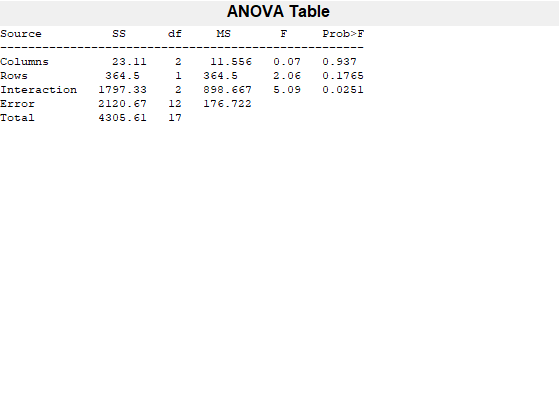

P =     0.9370    0.1765    0.0251


% Data skal omstruktureres, så det passer til
% ANOVA-funktionen
M = data(:,3:5);
M = M';
M = [M(:,1:3);M(:,4:6)];

P = anova2(M,n)


% Dette viser altså, at hypotese 1 og 2 ikke forkastes
% Hypotese 3 forkastes dog, og interaktionen er
% derfor den eneste indflydelse

Opgave c)

Analyser residualerne fra eksperimentet.

[R,VR,CM] = ANOVA2Residuals(M,n)

R =    12.0000   14.0000   -6.3333
    1.0000    1.0000    0.6667
  -13.0000  -15.0000    5.6667
    9.3333    9.6667    0.6667
    3.3333  -12.3333  -20.3333
  -12.6667    2.6667   19.6667


VR =    12.0000   14.0000   -6.3333    1.0000    1.0000    0.6667  -13.0000  -15.0000    5.6667    9.3333    9.6667    0.6667    3.3333  -12.3333  -20.3333  -12.6667    2.6667   19.6667


CM =    63.0000   59.0000   84.3333
   82.6667   85.3333   65.3333


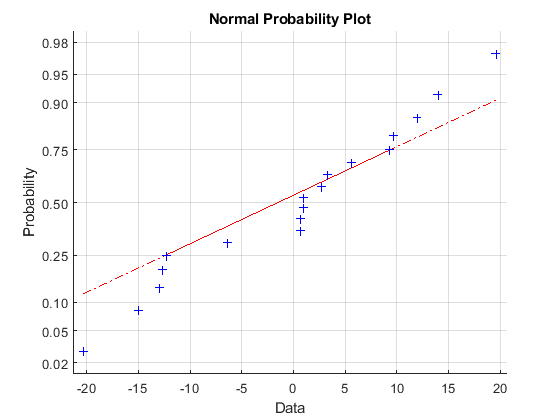

figure(4)
normplot(VR)